# AsteroidsAndBombsDataRead

Script for importing data from the following text file:

Auto-generated by MATLAB on 04-Nov-2019 17:56:21

## Setup the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 27);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Number", "Name", "Desig", "Family", "CS", "Class", "DiamS", "DiamF", "Diam", "HS", "HBand", "H", "GS", "G", "AlbS", "AlbF", "Albedo", "PF", "Period", "PerDesc", "AmpF", "AmpMin", "AmpMax", "U", "Pole", "BIN", "Notes"];
opts.VariableTypes = ["double", "string", "string", "categorical", "categorical", "categorical", "categorical", "string", "double", "categorical", "string", "double", "categorical", "double", "categorical", "string", "double", "categorical", "double", "string", "string", "double", "double", "double", "double", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Name", "Desig", "DiamF", "HBand", "AlbF", "PerDesc", "AmpF", "BIN", "Notes"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Name", "Desig", "Family", "CS", "Class", "DiamS", "DiamF", "HS", "HBand", "GS", "AlbS", "AlbF", "PF", "PerDesc", "AmpF", "BIN", "Notes"], "EmptyFieldRule", "auto");

% Import the data

tbl = readtable("LCDB_summary_20191104_184550.dat.txt", opts);

## Convert to output type

Number = tbl.Number;
Name = tbl.Name;
Desig = tbl.Desig;
Family = tbl.Family;
CS = tbl.CS;
Class = tbl.Class;
DiamS = tbl.DiamS;
DiamF = tbl.DiamF;
Diam = tbl.Diam;
HS = tbl.HS;
HBand = tbl.HBand;
H = tbl.H;
GS = tbl.GS;
G = tbl.G;
AlbS = tbl.AlbS;
AlbF = tbl.AlbF;
Albedo = tbl.Albedo;
PF = tbl.PF;
Period = tbl.Period;
PerDesc = tbl.PerDesc;
AmpF = tbl.AmpF;
AmpMin = tbl.AmpMin;
AmpMax = tbl.AmpMax;
U = tbl.U;
Pole = tbl.Pole;
BIN = tbl.BIN;
Notes = tbl.Notes;

## Clear temporary variables

clear opts tbl

length(Diam)

ans = 17367

length(Diam>0)

ans = 17367

Ceres=find(Name=='Ceres')

Ceres = 831

find(Name=='Duncan')


ans =

  0×1 empty double column vector



Shucks!

Period(Ceres)

ans = 9.0742

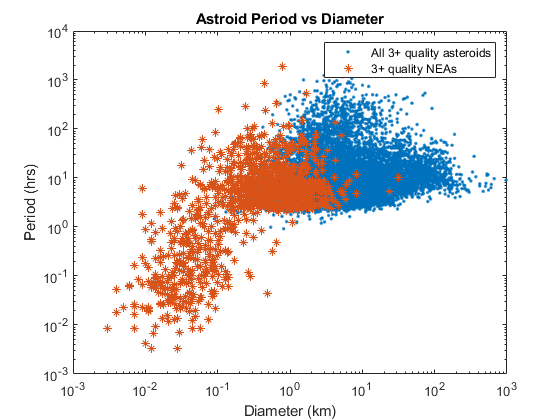

loglog(Diam,Period,'.')
hold on; 
loglog(Diam(Family=='NEA'), Period(Family=='NEA'),'*');
xlabel('Diameter (km)');
ylabel('Period (hrs)');
title('Astroid Period vs Diameter')
hold off
legend('All 3+ quality asteroids','3+ quality NEAs')